clear
clc

table = readtable("iFood6_CNN_history_2000_20.csv");
epochs = length(table.loss);

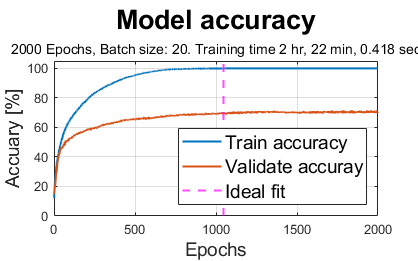

f = figure(1);
f.Position = [0,0,800,500];

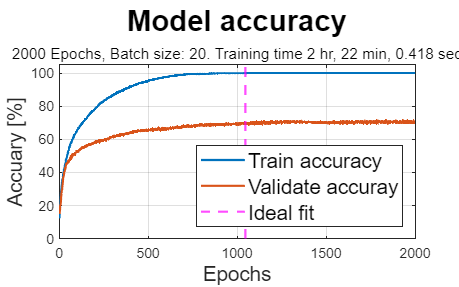

plot([table.accuracy,table.val_accuracy].*100,'LineWidth',1.5);
title("Model accuracy","FontSize",20);
subtitle(["2000 Epochs, Batch size: 20. Training time 2 hr, 22 min, 0.418 sec"])
xlabel("Epochs",'FontSize',14);
ylabel("Accuary [%]",'FontSize',14);
xlim([0 2000]);
ylim([0 105]);
grid on
idealfit = find(table.accuracy==1,1);
xline(idealfit,'m--','LineWidth',1.5)
text(idealfit+10,45,'Accuracy = 1','FontSize',14)
legend('Train accuracy','Validate accuray','Ideal fit','Location','southeast','FontSize',14)
saveas(1,"Model accuracy.png");

% Find local minima
lclMin = islocalmin(table.val_loss,"MaxNumExtrema",1);
f = figure(2);
f.Position = [0,0,800,500];
plot([table.loss,table.val_loss],'LineWidth',1.5);
title("Model losses","FontSize",20);
subtitle(["2000 Epochs, Batch size: 20. Training time 2 hr, 22 min, 0.418 sec"])
xlabel("Epochs",'FontSize',14);
ylabel("Loss",'FontSize',14);
xlim([0 2000]);
ylim([-1 17]);
grid on
fitline = find(lclMin==1,1)

fitline = 547

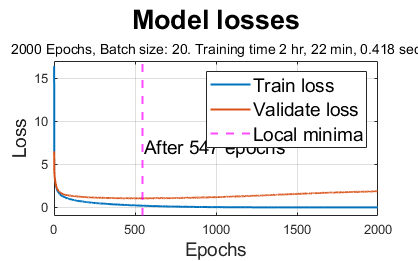

xline(fitline,'m--','LineWidth',1.5)
text(fitline+10,7,'After 547 epochs','FontSize',14)
legend('Train loss','Validate loss','Local minima','Location','northeast','FontSize',14)
saveas(2,"Model losses.png");